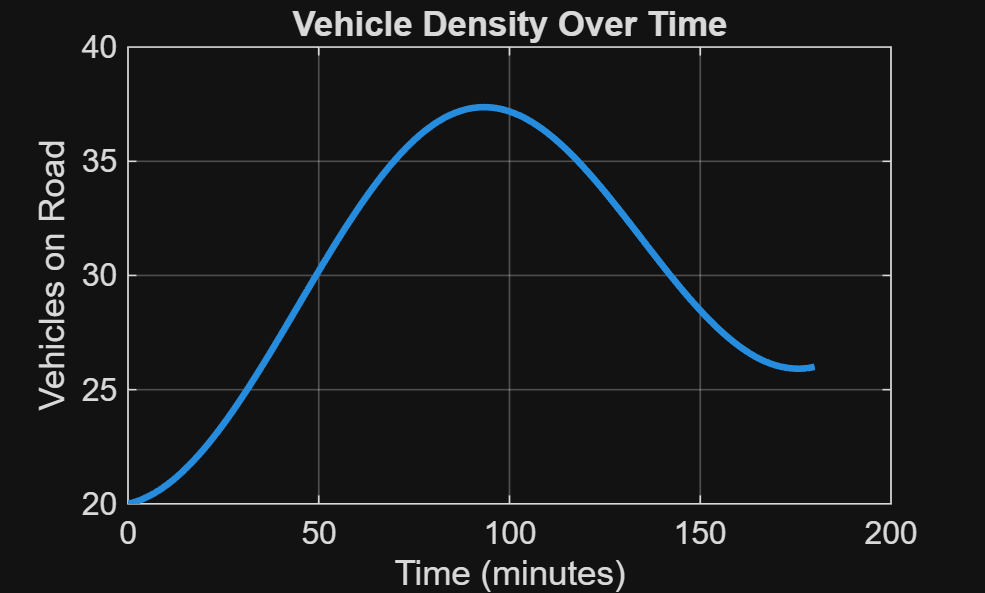

clc;
clear;
close all;

% Simulation parameters
dt = 1;                  % Time step (minutes)
t_end = 180;             % Total simulation time (minutes)

% Time vector
t = 0:dt:t_end;

% Road parameters
road_capacity = 120;     % Maximum vehicles
road_length = 1;         % km

% Initialize arrays
N = zeros(size(t));      % Vehicles on road
qin = zeros(size(t));    % Entry flow
qout = zeros(size(t));   % Exit flow
density = zeros(size(t));
speed = zeros(size(t));

% Traffic parameters
vf = 100;                % Free flow speed (km/h)
kj = 120;                % Jam density (veh/km)

% Initial condition
N(1) = 20;

for i = 2:length(t)

    % Variable inflow (rush hour effect)
    qin(i) = 20 + 15*sin(pi*t(i)/90);

    % Exit flow limited by congestion
    qout(i) = min(N(i-1), 18);

    % Update vehicle count
    N(i) = N(i-1) + (qin(i)-qout(i))*dt/60;

    % Limit maximum capacity
    if N(i) > road_capacity
        N(i) = road_capacity;
    end

    % Density calculation
    density(i) = N(i)/road_length;

    % Speed-density relationship
    speed(i) = vf*(1 - density(i)/kj);

    % Prevent negative speed
    if speed(i) < 0
        speed(i) = 0;
    end
end

% Flow calculation
flow = density .* speed;

%% Plot vehicle count
figure;
plot(t, N, 'LineWidth',2);
xlabel('Time (minutes)');
ylabel('Vehicles on Road');
title('Vehicle Density Over Time');
grid on;

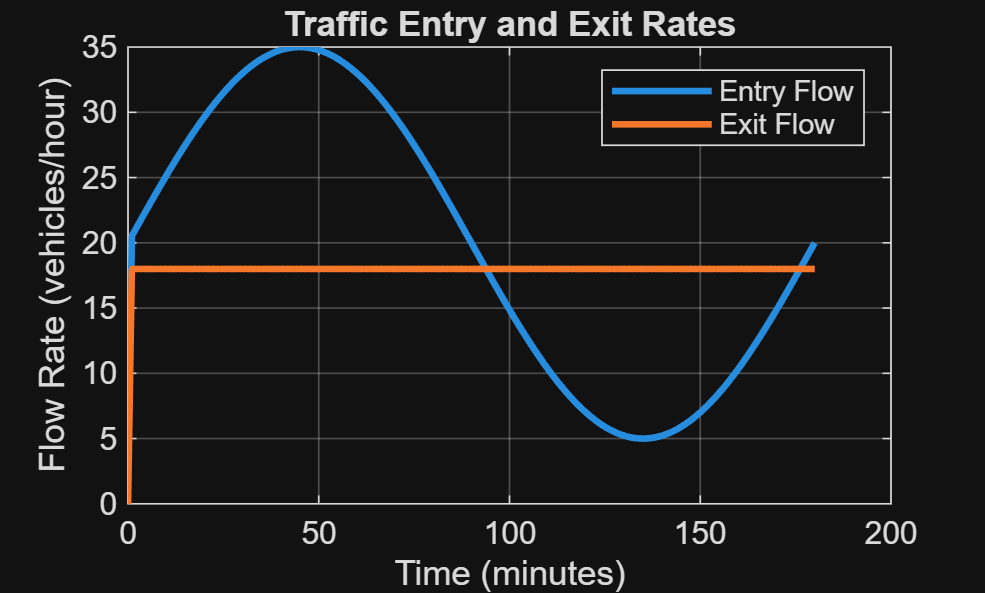


%% Plot inflow and outflow
figure;
plot(t, qin, 'LineWidth',2);
hold on;
plot(t, qout, 'LineWidth',2);
xlabel('Time (minutes)');
ylabel('Flow Rate (vehicles/hour)');
title('Traffic Entry and Exit Rates');
legend('Entry Flow','Exit Flow');
grid on;

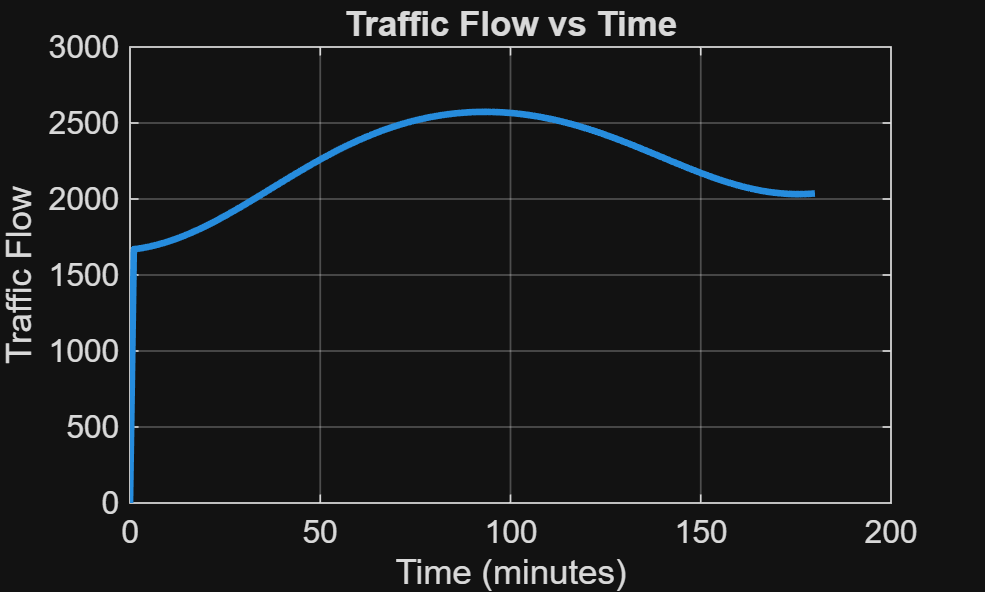


%% Plot flow
figure;
plot(t, flow, 'LineWidth',2);
xlabel('Time (minutes)');
ylabel('Traffic Flow');
title('Traffic Flow vs Time');
grid on;

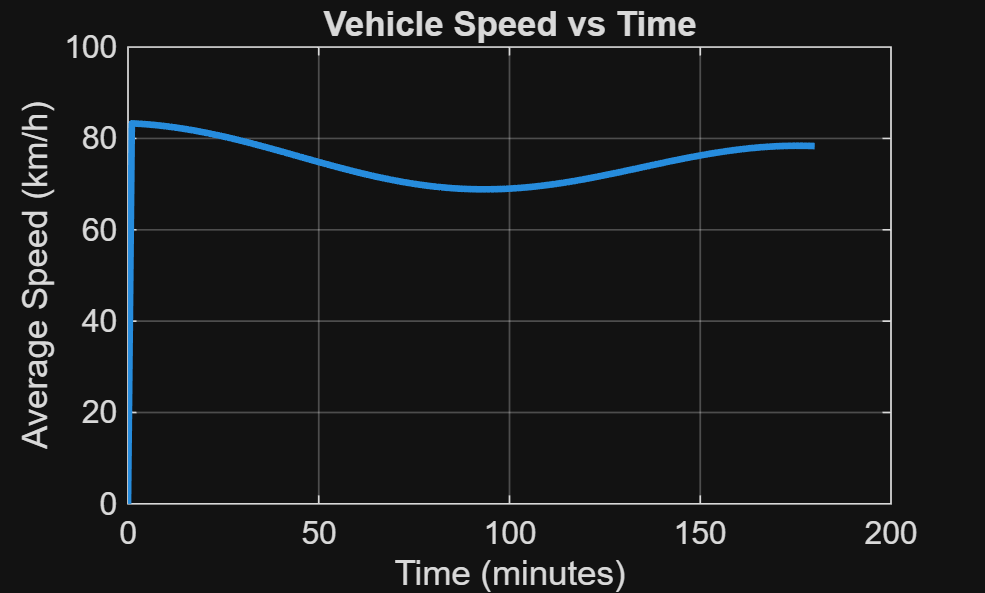


%% Plot speed
figure;
plot(t, speed, 'LineWidth',2);
xlabel('Time (minutes)');
ylabel('Average Speed (km/h)');
title('Vehicle Speed vs Time');
grid on;